In this file we make a fast comparison between Girls a Boys data computing a depth analysis.

load AlturaChicas.mat
load EdadChicas.mat
load AlturaChicos.mat

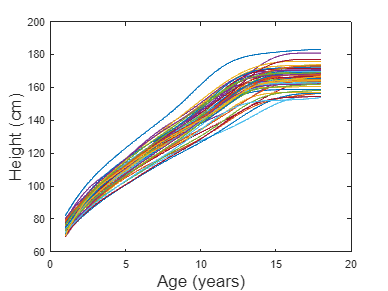

ages_interp = 1:0.05:18; % We establish a step of 0.05 years which allow us to construct different studies

figure();

predicted_girl_height_mat = zeros(length(ages_interp), 54); % Matrix to store predicted heights

for girl = 1:54
    heights_girl = hgtffit(:, girl);
    smoothingParam = 1;
 
    
    % Spline smoothing
    spline_result = spaps(age, heights_girl, smoothingParam,[], 3);
    predicted_heights = fnval(spline_result, ages_interp);
    predicted_heights = cummax(predicted_heights);
    
    predicted_girl_height_mat(:, girl) = predicted_heights; 
    
    plot(ages_interp, predicted_heights, '-');
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    xlim([0 20]);
    hold on
end

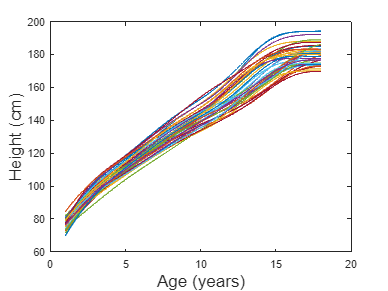

ages_interp = 1:0.05:18; 

figure();


predicted_boys_height_mat = zeros(length(ages_interp), 39); % Matriz para almacenar las alturas predichas

alturas = hgtmfit;

for man = 1:39
    edades_man = age;
    alturas_man = alturas(:, man);
    smoothingParam = 1;
 
    
    % Realiza el suavizado de splines
    spline_result = spaps(edades_man, alturas_man, smoothingParam, [], 3);
    predicted_heights = fnval(spline_result, ages_interp);
    predicted_heights = cummax(predicted_heights);
    
    predicted_boys_height_mat(:, man) = predicted_heights; % Almacena las alturas predichas en la matriz
    
    % Grafica los datos y la curva suavizada
    plot(ages_interp, predicted_heights, '-');
    xlabel('Age (years)','FontSize', 16);
    ylabel('Height (cm)','FontSize', 16);
    xlim([0 20]);
    hold on
end

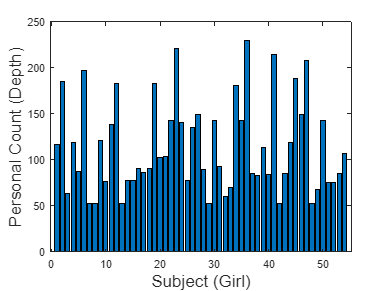

[n_ages, n_girls] = size(predicted_girl_height_mat);
personal_count_girl = zeros (54, 1);
C = nchoosek(1:54, 2);
b = nchoosek (54, 2);

% Loop to find the possible groups formed by 2 curves from the set
for i = 1:b
    girl1 = C(i, 1);
    girl2 = C(i, 2);
    
    superior_limit = max([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2)], [], 2);
    inferior_limit = min([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for girl3 = 1:n_girls
        if girl3 == girl1 || girl3 == girl2 
            personal_count_girl(girl3) = personal_count_girl(girl3) + 1;
        else
             % Verify if the curve is within the limits
            content = all(predicted_girl_height_mat(:, girl3) >= inferior_limit & predicted_girl_height_mat(:, girl3) <= superior_limit);
            % Increment personal_account if contained, that is, if contained is True
            if content
            personal_count_girl(girl3) = personal_count_girl(girl3) + 1;
            end
        end

    end
end

% personal_count contains the individual score of how many times each curve is contained between three other curves.
% The curve with the highest personal account will have the greatest depth.

personal_count_2_curves_girl = personal_count_girl; 
figure;
bar(personal_count_2_curves_girl);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal Count (Depth)','FontSize', 16);

nchoosek(54, 2) % If the curve is contained between all pairs, this value would be the personal count.

ans = 1431

We repeate the process but adding an extra curve to the limit in order to avoid intersection in pairs.

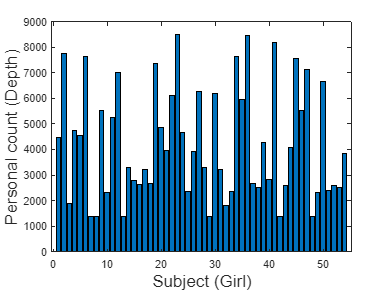

personal_count_girl = zeros (54, 1);
C = nchoosek(1:54, 3);
c = nchoosek (54, 3);

[n_ages, n_girl] = size(predicted_girl_height_mat);

% Loop to find the possible groups formed by 3 curves from the set
for i = 1:c
   girl1 = C(i, 1);
    girl2 = C(i, 2);
    girl3 = C(i, 3);
    
    superior_limit = max([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2), predicted_girl_height_mat(:, girl3)], [], 2);
    inferior_limit = min([predicted_girl_height_mat(:, girl1),predicted_girl_height_mat(:, girl2), predicted_girl_height_mat(:, girl3)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for girl4 = 1:n_girl
        if girl4 == girl1 || girl4 == girl2 || girl4 == girl3 
            personal_count_girl(girl4) = personal_count_girl(girl4) + 1;
        else

            % Verify if the curve is within the limits
            content = all(predicted_girl_height_mat(:, girl4) >= inferior_limit & predicted_girl_height_mat(:, girl4) <= superior_limit);
    
            % Increment personal_account if contained, that is, if contained is True
            if content
                personal_count_girl(girl4) = personal_count_girl(girl4) + 1;
            end
        end
    end
end


figure;
bar(personal_count_girl);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal count (Depth)','FontSize', 16);

nchoosek(54, 3) % If the curve is contained between all pairs, this value would be the personal count.

ans = 24804

The normalization of the data is usually done when working with different scales, it allow us to have a clearer representation.

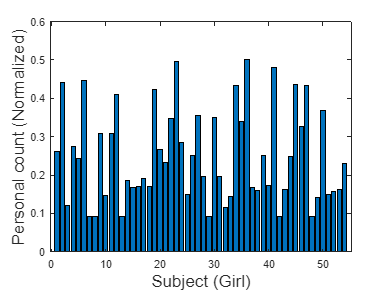


personal_count_2_curves_girl = personal_count_2_curves_girl / b; % Para 2 curvas como límites
personal_count_girl = personal_count_girl / c; % Para 3 curvas como límites
personal_count_girl = personal_count_girl + personal_count_2_curves_girl;


figure;
bar(personal_count_girl);
xlabel('Subject (Girl)','FontSize', 16);
ylabel('Personal count (Normalized)','FontSize', 16);

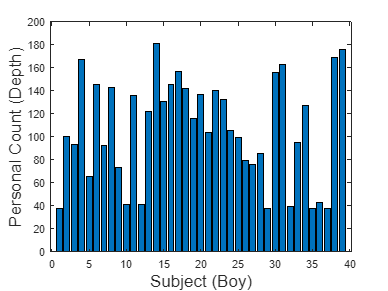

[n_ages, n_boys] = size(predicted_boys_height_mat);
personal_count_boy = zeros (39, 1);
C = nchoosek(1:39, 2);
b = nchoosek (39, 2);

% Loop to find the possible groups formed by 2 curves from the set
for i = 1:b
    boy1 = C(i, 1);
    boy2 = C(i, 2);
    
    superior_limit = max([predicted_boys_height_mat(:, boy1),predicted_boys_height_mat(:, boy2)], [], 2);
    inferior_limit = min([predicted_boys_height_mat(:, boy1),predicted_girl_height_mat(:, boy2)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for boy3 = 1:n_boys
        if boy3 == boy1 || boy3 == boy2 
            personal_count_boy(boy3) = personal_count_boy(boy3) + 1;
        else
             % Verify if the curve is within the limits
            content = all(predicted_boys_height_mat(:, boy3) >= inferior_limit & predicted_boys_height_mat(:, boy3) <= superior_limit);
            % Increment personal_account if contained, that is, if contained is True
            if content
            personal_count_boy(boy3) = personal_count_boy(boy3) + 1;
            end
        end

    end
end

% personal_count contains the individual score of how many times each curve is contained between three other curves.
% The curve with the highest personal account will have the greatest depth.

personal_count_2_curves_boy = personal_count_boy; 
figure;
bar(personal_count_2_curves_boy);
xlabel('Subject (Boy)','FontSize', 16);
ylabel('Personal Count (Depth)','FontSize', 16);

nchoosek(54, 2) % If the curve is contained between all pairs, this value would be the personal count.

ans = 1431

We repeate the process but adding an extra curve to the limit in order to avoid intersection in pairs.

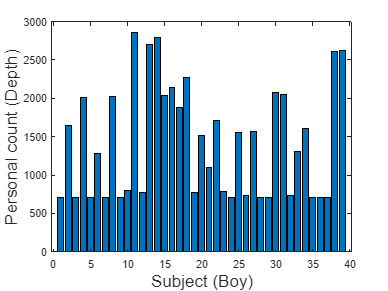

personal_count_boy = zeros (39, 1);
C = nchoosek(1:39, 3);
c = nchoosek (39, 3);

[n_ages, n_boys] = size(predicted_boys_height_mat);

% Loop to find the possible groups formed by 3 curves from the set
for i = 1:c
    boy1 = C(i, 1);
    boy2 = C(i, 2);
    boy3 = C(i, 3);
    
    superior_limit = max([predicted_boys_height_mat(:, boy1),predicted_boys_height_mat(:, boy2), predicted_boys_height_mat(:, boy3)], [], 2);
    inferior_limit = min([predicted_boys_height_mat(:, boy1),predicted_boys_height_mat(:, boy2), predicted_boys_height_mat(:, boy3)], [], 2);

    % Loop to study the rest of the curves with respect to the limit
    for boy4 = 1:n_boys
        if boy4 == boy1 || boy4 == boy2 || boy4 == boy3 
            personal_count_boy(boy4) = personal_count_boy(boy4) + 1;
        else

            % Verify if the curve is within the limits
            content = all(predicted_boys_height_mat(:, boy4) >= inferior_limit & predicted_boys_height_mat(:, boy4) <= superior_limit);
    
            % Increment personal_account if contained, that is, if contained is True
            if content
                personal_count_boy(boy4) = personal_count_boy(boy4) + 1;
            end
        end
    end
end


figure;
bar(personal_count_boy);
xlabel('Subject (Boy)','FontSize', 16);
ylabel('Personal count (Depth)','FontSize', 16);

nchoosek(54, 3) % If the curve is contained between all pairs, this value would be the personal count.

ans = 24804

The normalization of the data is usually done when working with different scales, it allow us to have a clearer representation.

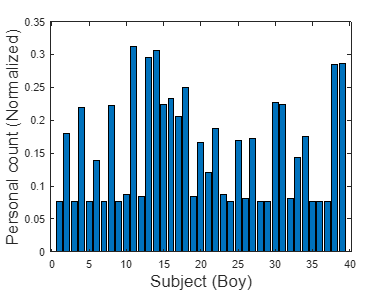


personal_count_2_curves_boy = personal_count_2_curves_boy / b; % Para 2 curvas como límites
personal_count_boy = personal_count_boy / c; % Para 3 curvas como límites
personal_count_boy = personal_count_boy + personal_count_2_curves_boy;


figure;
bar(personal_count_boy);
xlabel('Subject (Boy)','FontSize', 16);
ylabel('Personal count (Normalized)','FontSize', 16);

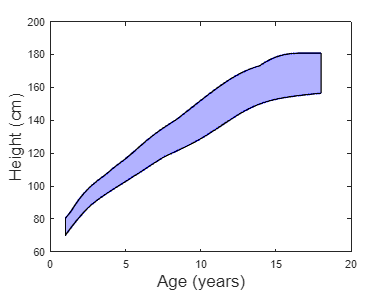

personal_count_girl = personal_count_girl + personal_count_2_curves_girl;

% We order the curves according to the depth measurement (normalised personal_count).
[~, ordered_indexes] = sort(personal_count_girl, 'descend');

% Select the 43 deepest curves (80 %). We can change the value to increase
% or decrease the range.

deepests_curves = ordered_indexes(1:43); 

% Initialize arrays to store the maximum and minimum values ��at each time
% point.
max_values = zeros(length(ages_interp), 1);
min_values = zeros(length(ages_interp), 1);

% Iterate over the selected curves to calculate the maximum and minimum
% values at each time point.
for i = 1:length(ages_interp)
    values = predicted_girl_height_mat(i, deepests_curves);
    max_values(i) = max(values);
    min_values(i) = min(values);
end


% Plot del rango de confianza
figure;

% Plot de las curvas difuminadas
plot(ages_interp, max_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva superior
hold on;
plot(ages_interp, min_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva inferior

% Rellenar la banda de color
fill([ages_interp.'; flipud(ages_interp.')], [max_values; flipud(min_values)], 'blue', 'FaceAlpha', 0.3);



xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([60, 200])
hold off

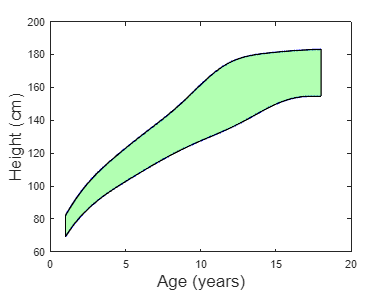


personal_count_boy = personal_count_boy + personal_count_2_curves_boy;

% We order the curves according to the depth measurement (normalised personal_count).
[~, ordered_indexes] = sort(personal_count_boy, 'descend');

% Select the 43 deepest curves (80 %). We can change the value to increase
% or decrease the range.

deepests_curves = ordered_indexes(1:31); 

% Initialize arrays to store the maximum and minimum values ��at each time
% point.
max_values = zeros(length(ages_interp), 1);
min_values = zeros(length(ages_interp), 1);

% Iterate over the selected curves to calculate the maximum and minimum
% values at each time point.
for i = 1:length(ages_interp)
    values = predicted_girl_height_mat(i, deepests_curves);
    max_values(i) = max(values);
    min_values(i) = min(values);
end


% Plot del rango de confianza

% Plot de las curvas difuminadas
plot(ages_interp, max_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva superior
hold on;
plot(ages_interp, min_values, 'b-', 'LineWidth', 1.5, 'Color', [0, 0, 1, 0.3]); % Difuminar curva inferior

% Rellenar la banda de color
fill([ages_interp.'; flipud(ages_interp.')], [max_values; flipud(min_values)], 'green', 'FaceAlpha', 0.3);



xlabel('Age (years)','FontSize', 16);
ylabel('Height (cm)','FontSize', 16);
ylim([60, 200])
hold off